# McNemar's Analysis of Bovine HD770K SNP Chip Data 

#### Case control study of bovine congestive heart failure (BCHF) as described in

### *Publication*: Association of ARRDC3 and NFIA variants with bovine congestive heart failure in feedlot cattle 

DOI : XXXXXXXX

Wrapper script to fire off McNemar's analysis. Assume PLINK files in current directory. Make sure scripts are in the command path. 

- This is an example script using SNP for chr28 only. 

- User must supply their own file FAM, PED, and MAP files for their own data.

- For computational efficiency, the PED files must be sorted by animal pair, then by control and case with control preceding the case in each pair in the PED. 

- Columns 1 - 6 in the PED are coded according to the following data Pair ID, Anim ID, PID, MID, SEX, PHENO. The control was coded with PHENO = 1 and case being coded with PHENO = 2 in column 6 of the PED. The control was and is expected to precede the case animal in every pair.

- The functions use the Parallel Computing and Statistics & Machine Learning Toolboxes.

**Inputs**: PED and MAP files

**Outputs**: McNemar's analysis in CSV file for each SNP in PED file

This script calls multiple custom functions according to the dependency graph below

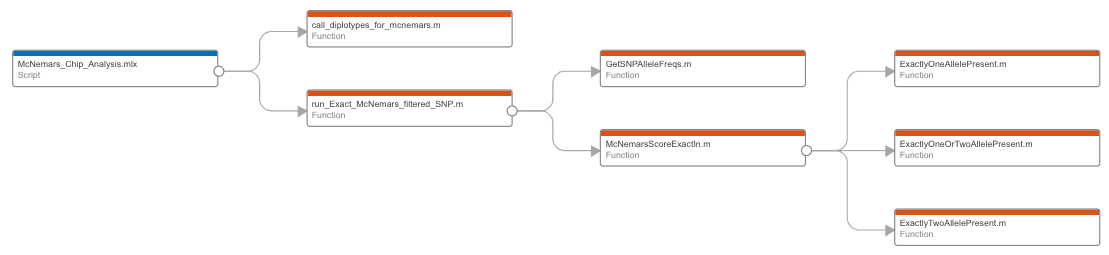

% start the timer 
tStartGenome = tic;

plinkMAP = 'BCHF102pairsHD770FFFSortFiltered_extract_chr28.map';
plinkPED = 'BCHF102pairsHD770FFFSortFiltered_extract_chr28.ped';
basename = 'BCHF102pairsHD770FFFSortFiltered_extract_chr28';

% create result file names and workspaces
McNemarsResultsFileName = strcat(basename,'.McNemarsResults.csv');
ChromoWorkSpace = strcat(basename,'.mat');

% call diplotypes, this is the time consuming step and has been
% parallelized using the Parallel Computing Toolbox within call_diplotypes_for_mcnemars
DiploType = call_diplotypes_for_mcnemars(plinkPED);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Elapsed time is 59.055749 seconds.


% run McNemar's
McNemarsResult = run_Exact_McNemars_filtered_SNP(DiploType,plinkMAP,...
    McNemarsResultsFileName);

Elapsed time is 22.983791 seconds.



% save workspace to binary file
save(ChromoWorkSpace);

% stop timer
tStopGenome = toc(tStartGenome);